clear
close all 
clc

load('Data-20251124/q.mat');   
load('Data-20251124/tau.mat'); 

q4   = q_meas(1:4, :);   
Tau4 = Tau(1:4, :);      

%% Conversion des unités
q_conv = q4;                            
q_conv([1 2 4], :) = deg2rad(q4([1 2 4], :));  
q_conv(3, :)       = q4(3, :) / 1000;          

fc = 10;          
fe = 1000;       
Wn = 2 * fc / fe;
[b, a] = butter(1, Wn); 

[n_joints, n_samples] = size(q_conv);

%% Initialisation
qf   = zeros(n_joints, n_samples);
dqf  = zeros(n_joints, n_samples);
ddqf = zeros(n_joints, n_samples);
tauf = zeros(n_joints, n_samples);

for i = 1:n_joints
    
    % Filtrage de la position 
    qf(i, :) = filtfilt(b, a, q_conv(i, :));
    
    % Filtrage des couples
    tauf(i, :) = filtfilt(b, a, Tau4(i, :));
    
    % Dérivation de la position filtrée
    dq_raw = derive(t, qf(i, :));
    
    % Filtrage de la vitesse
    dqf(i, :) = filtfilt(b, a, dq_raw);
    
    % Dérivation de la vitesse filtrée
    ddq_raw = derive(t, dqf(i, :));
    
    % Filtrage de l'accélération
    ddqf(i, :) = filtfilt(b, a, ddq_raw);
    
end


save("q_conv.mat", "q_conv");   
save("qf.mat",     "qf");
save("dqf.mat",    "dqf");
save("ddqf.mat",   "ddqf");
save("tauf.mat",   "tauf");


## **Affichage**

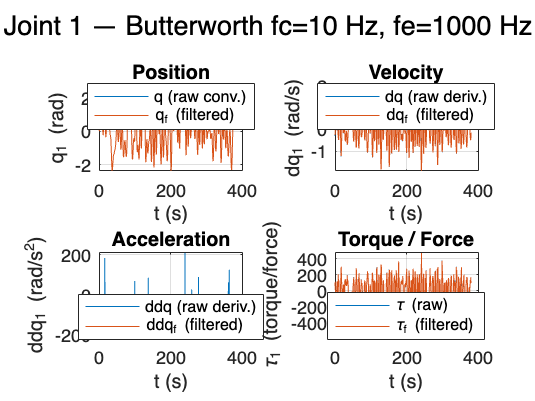

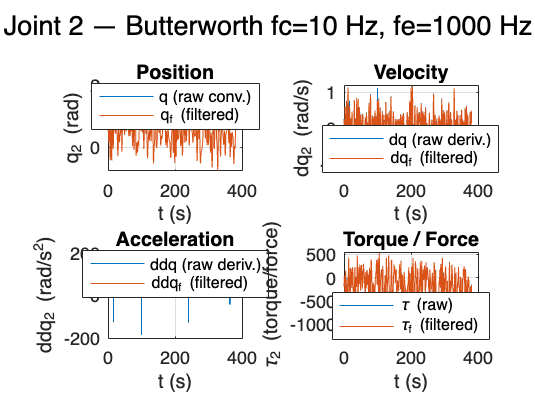

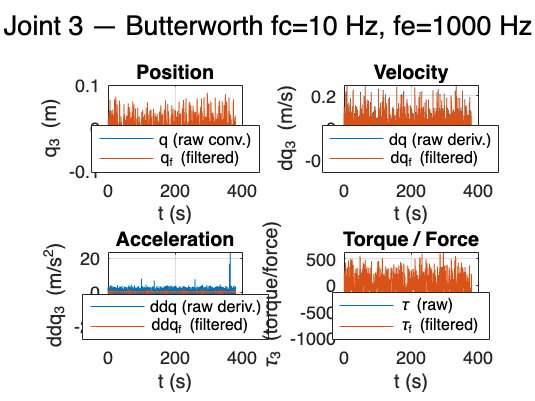

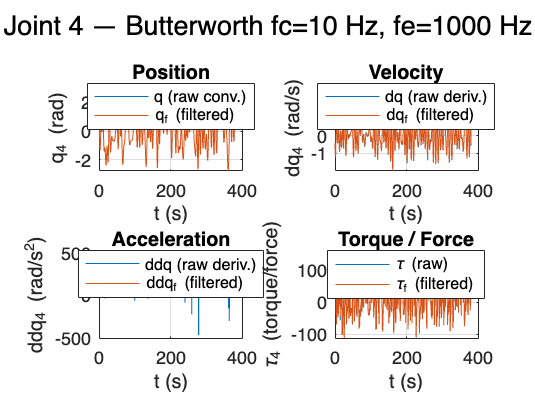


dq_raw_unf  = zeros(n_joints, n_samples);
ddq_raw_unf = zeros(n_joints, n_samples);

for jj = 1:n_joints
    dq_raw_unf(jj, :)  = derive(t, q_conv(jj, :));
    ddq_raw_unf(jj, :) = derive(t, dq_raw_unf(jj, :));
end

for jj = 1:n_joints
    
    if jj == 3
        unit_q   = 'm';
        unit_dq  = 'm/s';
        unit_ddq = 'm/s^2';
    else
        unit_q   = 'rad';
        unit_dq  = 'rad/s';
        unit_ddq = 'rad/s^2';
    end
    
    figure('Name', sprintf('Data processing - Joint %d', jj), 'NumberTitle', 'off');
    
    subplot(2,2,1);
    plot(t, q_conv(jj,:), 'DisplayName', 'q (raw conv.)'); hold on;
    plot(t, qf(jj,:),     'DisplayName', 'q_f (filtered)');
    grid on; xlabel('t (s)'); ylabel(sprintf('q_%d (%s)', jj, unit_q));
    title('Position'); legend('Location','best');
    
    subplot(2,2,2);
    plot(t, dq_raw_unf(jj,:), 'DisplayName', 'dq (raw deriv.)'); hold on;
    plot(t, dqf(jj,:),        'DisplayName', 'dq_f (filtered)');
    grid on; xlabel('t (s)'); ylabel(sprintf('dq_%d (%s)', jj, unit_dq));
    title('Velocity'); legend('Location','best');
    
    subplot(2,2,3);
    plot(t, ddq_raw_unf(jj,:), 'DisplayName', 'ddq (raw deriv.)'); hold on;
    plot(t, ddqf(jj,:),        'DisplayName', 'ddq_f (filtered)');
    grid on; xlabel('t (s)'); ylabel(sprintf('ddq_%d (%s)', jj, unit_ddq));
    title('Acceleration'); legend('Location','best');
    
    subplot(2,2,4);
    plot(t, Tau4(jj,:), 'DisplayName', '\tau (raw)'); hold on;
    plot(t, tauf(jj,:), 'DisplayName', '\tau_f (filtered)');
    grid on; xlabel('t (s)'); ylabel(sprintf('\\tau_%d (torque/force)', jj));
    title('Torque / Force'); legend('Location','best');
    
    sgtitle(sprintf('Joint %d — Butterworth fc=%g Hz, fe=%g Hz', jj, fc, fe));
end